# Analyzing Flight Volume

¿Qué relación existe entre el número de vuelos y el día de la semana? Por ejemplo, ¿hay más vuelos entre semana o los fines de semana? Investiguemos el volumen de vuelos entrantes en el Aeropuerto Internacional Logan de Boston durante el primer mes de 2015. Usemos los datos de vuelos de enero de 2015, "flightsJan.csv", utilizando la función importFlightsData.

## Initial Data Import and Volume Calculation

flights = importFlightsData("flightsJan.csv");

A continuación, extraiga el subconjunto de la tabla con los vuelos entrantes a Boston registrados.

flightsIntoBoston = flights(flights.DESTINATION == "BOS" , :);

Calculamos el volumen de vuelos usando [`groupsummary`](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html)`, utilizando la hora como tamaño de bin o barra.`

flightsIntoBoston.ACTUAL_ARRIVAL_HOUR = dateshift(flightsIntoBoston.ACTUAL_ARRIVAL_TIME,"start","hour"); 
flightsIntoBostonVolume = groupsummary(flightsIntoBoston,"ACTUAL_ARRIVAL_HOUR"); 
flightsIntoBostonVolume.Properties.VariableNames = [ "Arrival_Time" "Incoming_Flights" ]; % rename the variables for convenience 

Siempre es útil visualizar nuestros datos, veamos como se ve el histograma

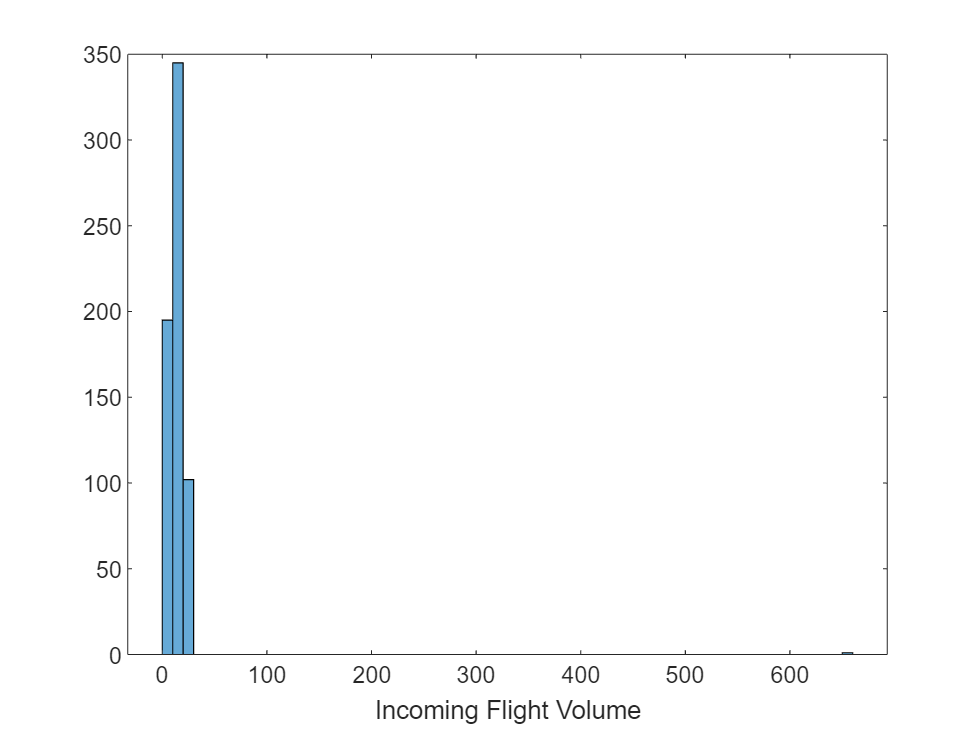

histogram(flightsIntoBostonVolume.Incoming_Flights); 
xlabel('Incoming Flight Volume'); 

Parece que la distribución se sitúa principalmente en el rango bajo, y puede que haya algunos puntos de datos muy altos por encima de 600. ¿Hubo realmente algunas horas con más de 600 vuelos de llegada? Investiguemos las horas correspondientes. Como nos interesan los datos más grandes del volumen de vuelos, ordenemos las filas de la tabla por esta variable en orden descendente.

sortrows(flightsIntoBostonVolume,"Incoming_Flights","descend")

ans = 643×2 table
        Arrival_Time        Incoming_Flights
    ____________________    ________________

                     NaT          659       
    15-Jan-2015 16:00:00           27       
    05-Jan-2015 16:00:00           26       
    12-Jan-2015 17:00:00           26       
    14-Jan-2015 21:00:00           26       
    21-Jan-2015 16:00:00           26       
    23-Jan-2015 17:00:00           26       
    06-Jan-2015 23:00:00           25       
    15-Jan-2015 21:00:00           25       
    16-Jan-2015 16:00:00           25       
    30-Jan-2015 20:00:00           25       
    05-Jan-2015 15:00:00           24       
    08-Jan-2015 17:00:00           24       
    13-Jan-2015 17:00:00           24       
    20-Jan-2015 17:00:00           24       
    21-Jan-2015 23:00:00           24       


### Cleaning Missing Data

Se puede observar que el número extremadamente elevado de vuelos de llegada corresponde a una entrada que falta en los datos horarios. Lo más probable es que estos "vuelos sin hora" se deban a vuelos cancelados o desviados que no tenían ninguna entrada para la hora de llegada. En cualquier caso, puede eliminar estos datos. La forma más sencilla de hacerlo en este punto es utilizando la función [rmmissing](https://www.mathworks.com/help/matlab/ref/rmmissing.html). Dada una tabla, eliminará cualquier fila en la que falte una entrada en cualquier variable. 

flightsIntoBostonVolume = rmmissing(flightsIntoBostonVolume)

flightsIntoBostonVolume = 642×2 table
        Arrival_Time        Incoming_Flights
    ____________________    ________________

    01-Jan-2015 06:00:00            1       
    01-Jan-2015 07:00:00            4       
    01-Jan-2015 08:00:00            4       
    01-Jan-2015 09:00:00           11       
    01-Jan-2015 10:00:00           10       
    01-Jan-2015 11:00:00            7       
    01-Jan-2015 12:00:00            9       
    01-Jan-2015 13:00:00           12       
    01-Jan-2015 14:00:00           10       
    01-Jan-2015 15:00:00           18       
    01-Jan-2015 16:00:00           22       
    01-Jan-2015 17:00:00           15       
    01-Jan-2015 18:00:00           17       
    01-Jan-2015 19:00:00           14       
    01-Jan-2015 20:00:00            9       
    01-Jan-2015 21:00:00           11       


Ahora que esta entrada ha desaparecido, veamos de nuevo el histograma para ver si hay otros problemas obvios en los datos hasta ahora. 

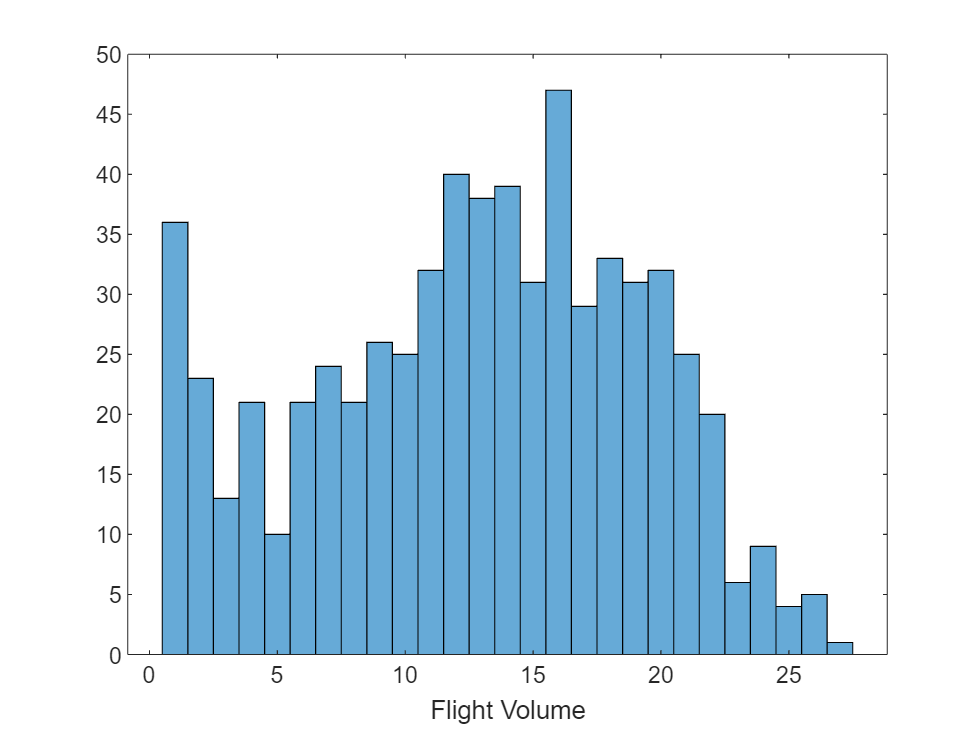

histogram(flightsIntoBostonVolume.Incoming_Flights); 
xlabel('Flight Volume'); 

Parece que los números restantes para el volumen de vuelo están todos más juntos y en un rango más razonable. Dado que sólo había un valor extremadamente grande en los datos de vuelo entrantes, podría haber utilizado la función [rmoutliers](https://www.mathworks.com/help/matlab/ref/rmoutliers.html) para eliminarlo.

## Flight Volume vs. Weekend Status

Ahora ya estamos listo para empezar a investigar si existe alguna relación entre el día de la semana y el volumen de vuelos entrantes. Para empezar, tendremos que añadir una variable a la tabla que indique si una entrada de volumen de vuelos se produjo en fin de semana o entre semana. Utilizaremos la función [isweekend](https://www.mathworks.com/help/matlab/ref/datetime.isweekend.html) para esto.  

flightsIntoBostonVolume.Weekend = isweekend(flightsIntoBostonVolume.Arrival_Time);

Ahora usamos [`stackedplot`](https://www.mathworks.com/help/matlab/ref/stackedplot.html) para comparar el volumen de vuelos con el indicador de fin de semana con el mismo eje x. 

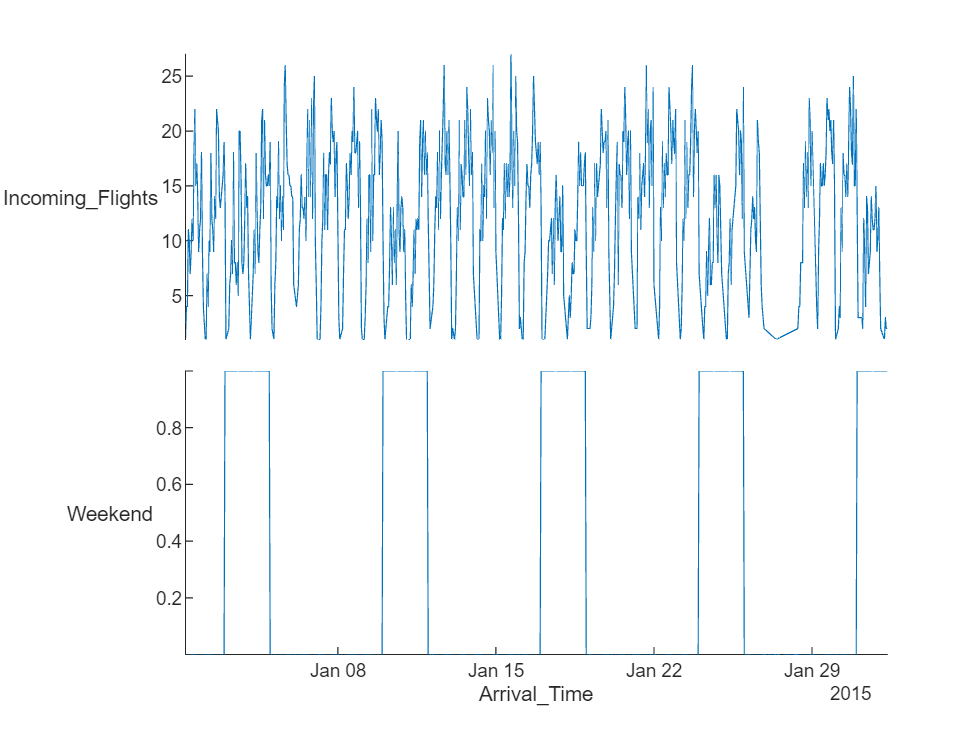

stackedplot(flightsIntoBostonVolume,"XVariable","Arrival_Time");

Observando el resultado, parece que puede haber algunos puntos en los que exista una relación aproximadamente inversa entre el volumen de vuelos y el fin de semana. Sin embargo, esto no está muy claro. Calculemos la correlación entre el volumen de vuelos entrantes y el fin de semana. 

corrVolumeWeekend = corr(flightsIntoBostonVolume.Incoming_Flights,flightsIntoBostonVolume.Weekend)

### Smoothing Data 

A negative correlation certainly supports the idea that there may be an inverse relationship overall, but the flight volume includes a lot of short-term variation compared to the weekend indicator. Let's try smoothing the flight volume to reveal a potential relationship more fully. Start by using a centered moving median window one day in length. (Note: if you had not removed the missing entries from the table, you would get errors attempting to do this.) 

Una correlación negativa apoya la idea de que puede haber una relación inversa en general, pero el volumen de vuelos incluye mucha variación a corto plazo en comparación con el indicador de fin de semana. Intentemos suavizar el volumen de vuelos para revelar mejor una posible relación. Empecemos utilizando una ventana mediana móvil centrada de un día de duración. (Nota: si hay datos faltantes en la tabla, habrá errores al intentar hacer esto). 

% Smooth input data
smoothedFlightVolume = smoothdata(flightsIntoBostonVolume.Incoming_Flights,...
    'movmedian',days(1),'SamplePoints',flightsIntoBostonVolume.Arrival_Time);


Ahora volvamos a visualizar la comparación utilizando [`stackedplot`](https://www.mathworks.com/help/matlab/ref/stackedplot.html), pero esta vez con la variable smoothedFlightVolume que acabamos de crear. 

stackedplot(flightsIntoBostonVolume.Arrival_Time, [ smoothedFlightVolume , flightsIntoBostonVolume.Weekend ] ,"DisplayLabels",["Smoothed Flight Volume" "Weekend Indicator"] );

Visualmente, el volumen de vuelos suavizado con la ventana mediana de un día tiene una relación inversa mucho más clara con el indicador de fin de semana. También podemos comprobar el cambio correspondiente en el coeficiente de correlación.

corrSmoothVolumeWeeeknd = corr(smoothedFlightVolume,flightsIntoBostonVolume.Weekend)

### Normalizing Data

Otra forma de visualizar la relación es superponiendo los dos gráficos. Haciéndolo con los resultados anteriores se obtiene la siguiente figura. 

plot(flightsIntoBostonVolume.Arrival_Time,smoothedFlightVolume); 
hold on; 
plot(flightsIntoBostonVolume.Arrival_Time,flightsIntoBostonVolume.Weekend); 
hold off; 
legend(["Smoothed Volume","Weekend Indicator"],"Location","best"); 

La visualización puede mejorarse significativamente normalizando el indicador de volumen para que se ajuste más al indicador binario de fin de semana. 

normalizedSmoothedFlightVolume = normalize(smoothedFlightVolume); 

plot(flightsIntoBostonVolume.Arrival_Time,normalizedSmoothedFlightVolume); 
hold on; 
plot(flightsIntoBostonVolume.Arrival_Time,flightsIntoBostonVolume.Weekend);
hold off; 
legend(["Normalized Smoothed Volume","Weekend Indicator"],"Location","best"); 

### Removing Outliers

You can see that almost all the time when the weekend indicator is high, the volume indicator is low, and vice versa. However, there is a notable exception to this trend around January 27th. This data point seems unusual for the volume indicator since it is far out of the typical range. Let's try identifying and removing outliers from the normalized volume indicator and comparing the remaining data to the corresponding weekend indicator again. 

Podemos observar que normalmente cuando el indicador de fin de semana es alto, el indicador de volumen es bajo, y viceversa. Sin embargo, hay una notable excepción a esta tendencia en torno al 27 de enero. Este punto de datos parece inusual para el indicador de volumen, ya que está muy lejos del rango típico. Intentemos identificar y eliminar los valores atípicos del indicador de volumen normalizado y comparemos de nuevo los datos restantes con el indicador de fin de semana correspondiente. 

smoothedFlightVolumeOutlierIdx = isoutlier(normalizedSmoothedFlightVolume); 
newSmoothedFlightVolume = normalize(smoothedFlightVolume(~smoothedFlightVolumeOutlierIdx)); 
newWeekend = flightsIntoBostonVolume.Weekend(~smoothedFlightVolumeOutlierIdx); 
newArrivalTime = flightsIntoBostonVolume.Arrival_Time(~smoothedFlightVolumeOutlierIdx); 
plot(newArrivalTime,newSmoothedFlightVolume); 
hold on; 
plot(newArrivalTime,newWeekend);
hold off; 
legend(["Volume Indicator","Weekend Indicator"],"Location","best"); 
newCorrSmoothVolumeWeeeknd = corr(newSmoothedFlightVolume,newWeekend)

Un pequeño aumento, pero no hay mucha diferencia. Mirando la figura todavía hay un par de puntos obvios que no siguen la tendencia alrededor del 27 de enero. ¿que pasó en Boston del 26 al 28 de enero de 2015?. 

[https://en.wikipedia.org/wiki/January_2015_North_American_blizzard#Impact](https://en.wikipedia.org/wiki/January_2015_North_American_blizzard#Impact)

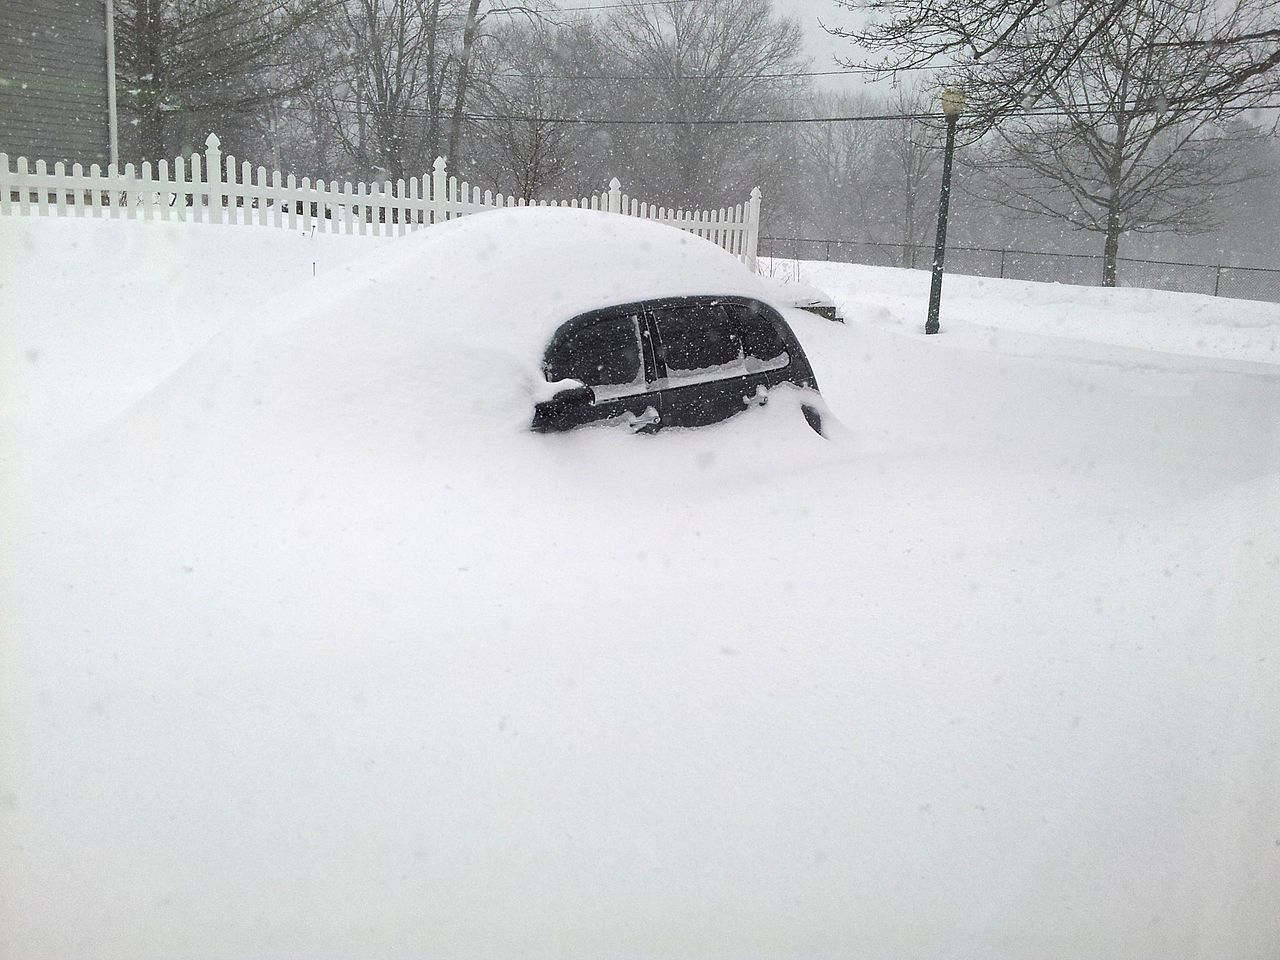

## Summary

Vimos brevemente como tratar datos faltantes, atípicos, filtrado (smoothing) y normalización. Combinamos estas técnicas para descubrir una correlación entre el volumen de vuelos y el día de la semana. Esta relación no estaba clara en absoluto en los datos brutos, pero descubrimos gradualmente la tendencia a través de una serie de pasos de limpieza. El conjunto concreto de pasos necesarios para limpiar nuevos datos dependerá completamente del escenario y de los objetivos del análisis.